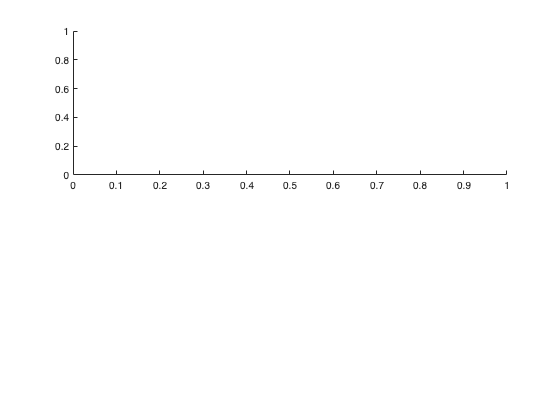

figure;


subplot(2,1,1)

opt = stepDataOptions('StepAmplitude',1);
step(PC_trav_techo/(1+PC_trav_techo),opt)

Unrecognized function or variable 'PC_trav_techo'.

hold on
step(PC_trav_gyro2/(1+PC_trav_gyro2))
grid on
title('Step Response 1[rad/s] Close Loop traverse techo/gyro')
legend({'traverse techo','traverse gyro'})

subplot(2,1,2)
step(PC_trav_techo/(1+PC_trav_techo),opt,5)
hold on
step(PC_trav_gyro2/(1+PC_trav_gyro2),opt,5)
grid on
title('Step Response 1[rad/s] Close Loop traverse techo/gyro')
legend({'traverse techo','traverse gyro'})


step_info_trav_techo_1 = stepinfo(PC_trav_techo/(1+PC_trav_techo))
step_info_trav_gyro_1 =stepinfo(PC_trav_gyro2/(1+PC_trav_gyro2))


figure;

subplot(2,1,1)
opt = stepDataOptions('StepAmplitude',0.05);
step((PC_trav_techo/(1+PC_trav_techo)),opt)
hold on
step((PC_trav_gyro2/(1+PC_trav_gyro2)),opt)
grid on
title('Step Response 0.05[rad/s] Close Loop traverse techo/gyro')
legend({'traverse techo','traverse gyro'})


subplot(2,1,2)
opt = stepDataOptions('StepAmplitude',0.05);
step((PC_trav_techo/(1+PC_trav_techo)),opt,5)
hold on
step((PC_trav_gyro2/(1+PC_trav_gyro2)),opt,5)
grid on
title('Step Response 0.05[rad/s] Close Loop traverse techo/gyro')
legend({'traverse techo','traverse gyro'})


step_info_trav_techo_005 = stepinfo(0.05*PC_trav_techo/(1+PC_trav_techo))
step_info_trav_gyro_005 =stepinfo(0.05*PC_trav_gyro2/(1+PC_trav_gyro2))

figure;

subplot(2,1,1)
opt = stepDataOptions('StepAmplitude',1);
step(PC_elev_techo/(1+PC_elev_techo),opt,2)
hold on
step(PC_elev_gyro/(1+PC_elev_gyro),opt,2)
grid on
title('Step Response 1[rad/s] Close Loop traverse techo/gyro')
legend({'elevation techo','elevation gyro'})

subplot(2,1,2)
step(PC_elev_techo/(1+PC_elev_techo),opt,5)
hold on
step(PC_elev_gyro/(1+PC_elev_gyro),opt,5)
grid on
title('Step Response 1[rad/s] Close Loop traverse techo/gyro')
legend({'elevation techo','elevation gyro'})

step_info_elev_techo_1 = stepinfo(PC_elev_techo/(1+PC_elev_techo))
step_info_elev_gyro_1 =stepinfo(PC_elev_gyro/(1+PC_elev_gyro))

figure;

subplot(2,1,1)
opt = stepDataOptions('StepAmplitude',0.05);
step((PC_elev_techo/(1+PC_elev_techo)),opt,2)

hold on
step((PC_elev_gyro/(1+PC_elev_gyro)),opt,2)

grid on
title('Step Response 0.05[rad/s] Close Loop traverse techo/gyro')
legend({'elevation techo','elevation gyro'})


subplot(2,1,2)

opt = stepDataOptions('StepAmplitude',0.05);
step((PC_elev_techo/(1+PC_elev_techo)),opt,5)
hold on
step((PC_elev_gyro/(1+PC_elev_gyro)),opt,5)
grid on
title('Step Response 0.05[rad/s] Close Loop elaevation techo/gyro')
legend({'elevation techo','elevation gyro'})

step_info_elev_techo_005 = stepinfo(0.05*PC_elev_techo/(1+PC_elev_techo))
step_info_elev_gyro_005 =stepinfo(0.05*PC_elev_gyro/(1+PC_elev_gyro))

s = tf('s');
sys = PC_trav_gyro2/(1+PC_trav_gyro2);
[y,t]=step(sys/s); 
PC_trav_gyro2_sserror=abs(t(end)-y(end)) 
sys = PC_trav_techo/(1+PC_trav_techo);
[y,t]=step(sys/s); 
PC_trav_techo_sserror=abs(t(end)-y(end))
sys = PC_elev_techo/(1+PC_elev_techo);
[y,t]=step(sys/s); 
PC_elev_techo_sserror=abs(t(end)-y(end))
sys = PC_elev_gyro/(1+PC_elev_gyro);
[y,t]=step(sys/s); 
PC_elev_gyro_sserror=abs(t(end)-y(end))